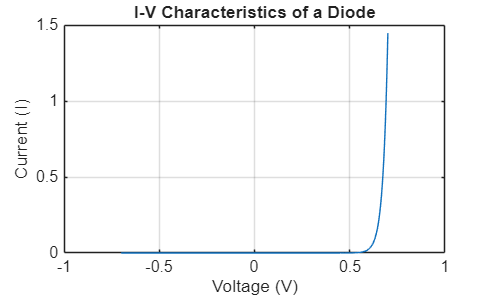

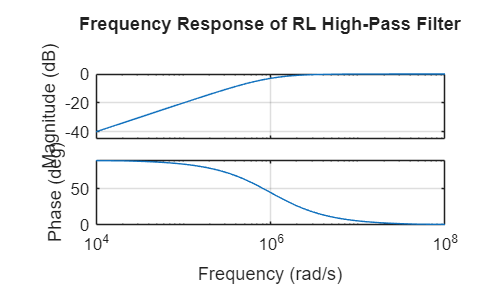

Collector-Emitter Voltage: 5 V


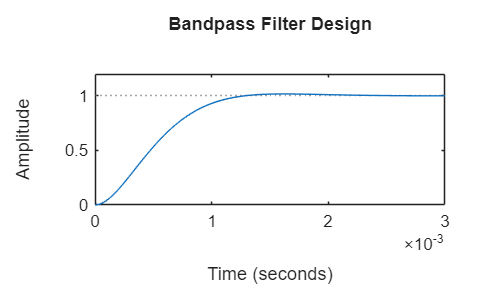

%% Example 01
% Problem: Calculates and plot the current-voltage (I-V) characteristics of a diode, 
% showing how the diode current changes with applied voltage from -0.7 V to +0.7 V.

% Saturation current and thermal voltage
Is = 1e-12; 
Vt = 0.025; 

% Voltage sweep from -0.7V to 0.7V
V = linspace(-0.7, 0.7, 1000);

% Shockley diode equation
I = Is * (exp(V/Vt) - 1);

% Plotting I-V curve
plot(V, I);
xlabel('Voltage (V)');
ylabel('Current (I)');
title('I-V Characteristics of a Diode');
grid on;

%% Example 02
% Problem: Create the transfer function of an RL high-pass filter using resistance 
% and inductance values, then plot its frequency response using a Bode plot.

% Component values
R = 1e3; % Resistor = 1k ohm
L = 1e-3; % Inductor = 1mH

% Transfer function H(s) = Ls / (Ls + R)
H = tf([L 0], [L R]);

% Bode plot for frequency response
bode(H);
title('Frequency Response of RL High-Pass Filter');
grid on;

%% Example 03
% Problem: Create the transfer function of a series RLC circuit using resistance, 
% inductance, and capacitance values, then plots its step response to show how 
% the circuit behaves over time.

% Circuit values
R = 5;       % Resistance in ohms
L = 1e-3;    % Inductance in henrys
C = 100e-6;  % Capacitance in farads

% Transfer function for series RLC
sys = tf([1], [L*C R*C 1]);

% Plot step response
step(sys);
title('Series RLC Circuit Step Response');


%% Example 04
% Problem: Calculate the collector-emitter voltage of a BJT common-emitter amplifier 
% using the transistor's current gain, base current, and collector resistance, 
% producing an output of 5 V.

% Circuit parameters
beta = 100;     % Current gain
R_C = 1e3;      % Collector resistor (1k ohm)
V_CC = 10;      % Supply voltage (10V)
I_B = 50e-6;    % Base current (50 uA)

% Calculate currents and Vce
I_C = beta * I_B;           % Collector current
V_CE = V_CC - (I_C * R_C);  % Collector-emitter voltage

% Print result
disp(['Collector-Emitter Voltage: ', num2str(V_CE), ' V']);


%% Example 05
% Problem: Designs a 50th-order FIR bandpass filter that allows frequencies 
% between 100 Hz and 200 Hz to pass while attenuating other frequencies, 
% and displays its frequency response.

% Filter settings
Fs = 1000;     % Sampling frequency
Fpass1 = 100;  % Lower cutoff frequency
Fpass2 = 200;  % Upper cutoff frequency
N = 50;        % Filter order

% Design the FIR bandpass filter
bpFilt = designfilt('bandpassfir', 'FilterOrder', N, ...
    'CutoffFrequency1', Fpass1, 'CutoffFrequency2', Fpass2, ...
    'SampleRate', Fs);

% Visualize the filter response
fvtool(bpFilt);
title('Bandpass Filter Design');

% Problem: Calculate the output voltage of an inverting op-amp amplifier with a gain of -10, producing an output of -10 V from a 1 V input.

% Resistor values and input voltage
Rin = 10e3;    % Input resistor = 10k ohm
Rf = 100e3;    % Feedback resistor = 100k ohm
Vin = 1;       % Input voltage = 1V

% Calculate gain and output voltage
Av = -Rf / Rin;
Vout = Av * Vin;

% Display output voltage
disp(['Output Voltage: ', num2str(Vout), ' V']);

% Problem: Create the transfer function of an RC circuit using resistance and capacitance values, then plot its transient response to an impulse input over time.

% Component values
R = 1e3;    % Resistance = 1k ohm
C = 1e-6;   % Capacitance = 1 uF

% Transfer function H(s) = 1 / (R*C*s + 1)
sys = tf([1], [R*C 1]);

% Plot impulse response
impulse(sys);
title('Transient Response of RC Circuit');

% Problem: Calculate and display the magnitude of the total impedance of a series RLC circuit at 60 Hz using its resistance, inductance, and capacitance values.

% Component values and signal frequency
R = 50;        % Resistance = 50 ohms
L = 100e-3;    % Inductance = 100 mH
C = 10e-6;     % Capacitance = 10 uF
f = 60;        % Frequency = 60 Hz

% Calculate angular frequency and complex impedance
omega = 2 * pi * f;
Z = R + 1i * (omega * L - 1 / (omega * C));

% Display impedance magnitude
disp(['Impedance: ', num2str(abs(Z)), ' Ohms']);

% Problem: Simulate a Schmitt trigger circuit by calculating its upper and lower threshold voltages (+-4.55 V) and plotting how the output switches between +5 V and -5 V as the input voltage changes.

% Circuit voltages and resistors
Vcc = 5;      % Supply voltage = 5V
R1 = 1e3;     % R1 = 1k ohm
R2 = 10e3;    % R2 = 10k ohm

% Threshold calculations
Vh = Vcc * (R2 / (R1 + R2));
Vl = -Vcc * (R2 / (R1 + R2));

% Input voltage sweep from -5V to +5V
Vin = linspace(-Vcc, Vcc, 1000);
Vout = zeros(size(Vin));

% Loop through input values to apply hysteresis
for i = 2:length(Vin)
    if Vin(i) > Vh
        Vout(i) = Vcc;
    elseif Vin(i) < Vl
        Vout(i) = -Vcc;
    else
        Vout(i) = Vout(i-1);
    end
end

% Plot switching characteristic
plot(Vin, Vout);
title('Schmitt Trigger Circuit');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
grid on;


% Problem: Simulate a full-wave rectifier by converting a 50 Hz AC sine wave into a pulsating positive voltage and plotting both the input and output waveforms.

% Time vector for 0.1 seconds
t = linspace(0, 0.1, 1000);

% 50 Hz AC input signal
Vin = sin(2 * pi * 50 * t);

% Full-wave rectification (absolute value)
Vout = abs(Vin);

% Plot both waveforms
plot(t, Vin, t, Vout);
title('Full-Wave Rectifier Simulation');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('Input Voltage', 'Output Voltage');
grid on;